## **Driver test program to check Clothoids library**

**Polylines**

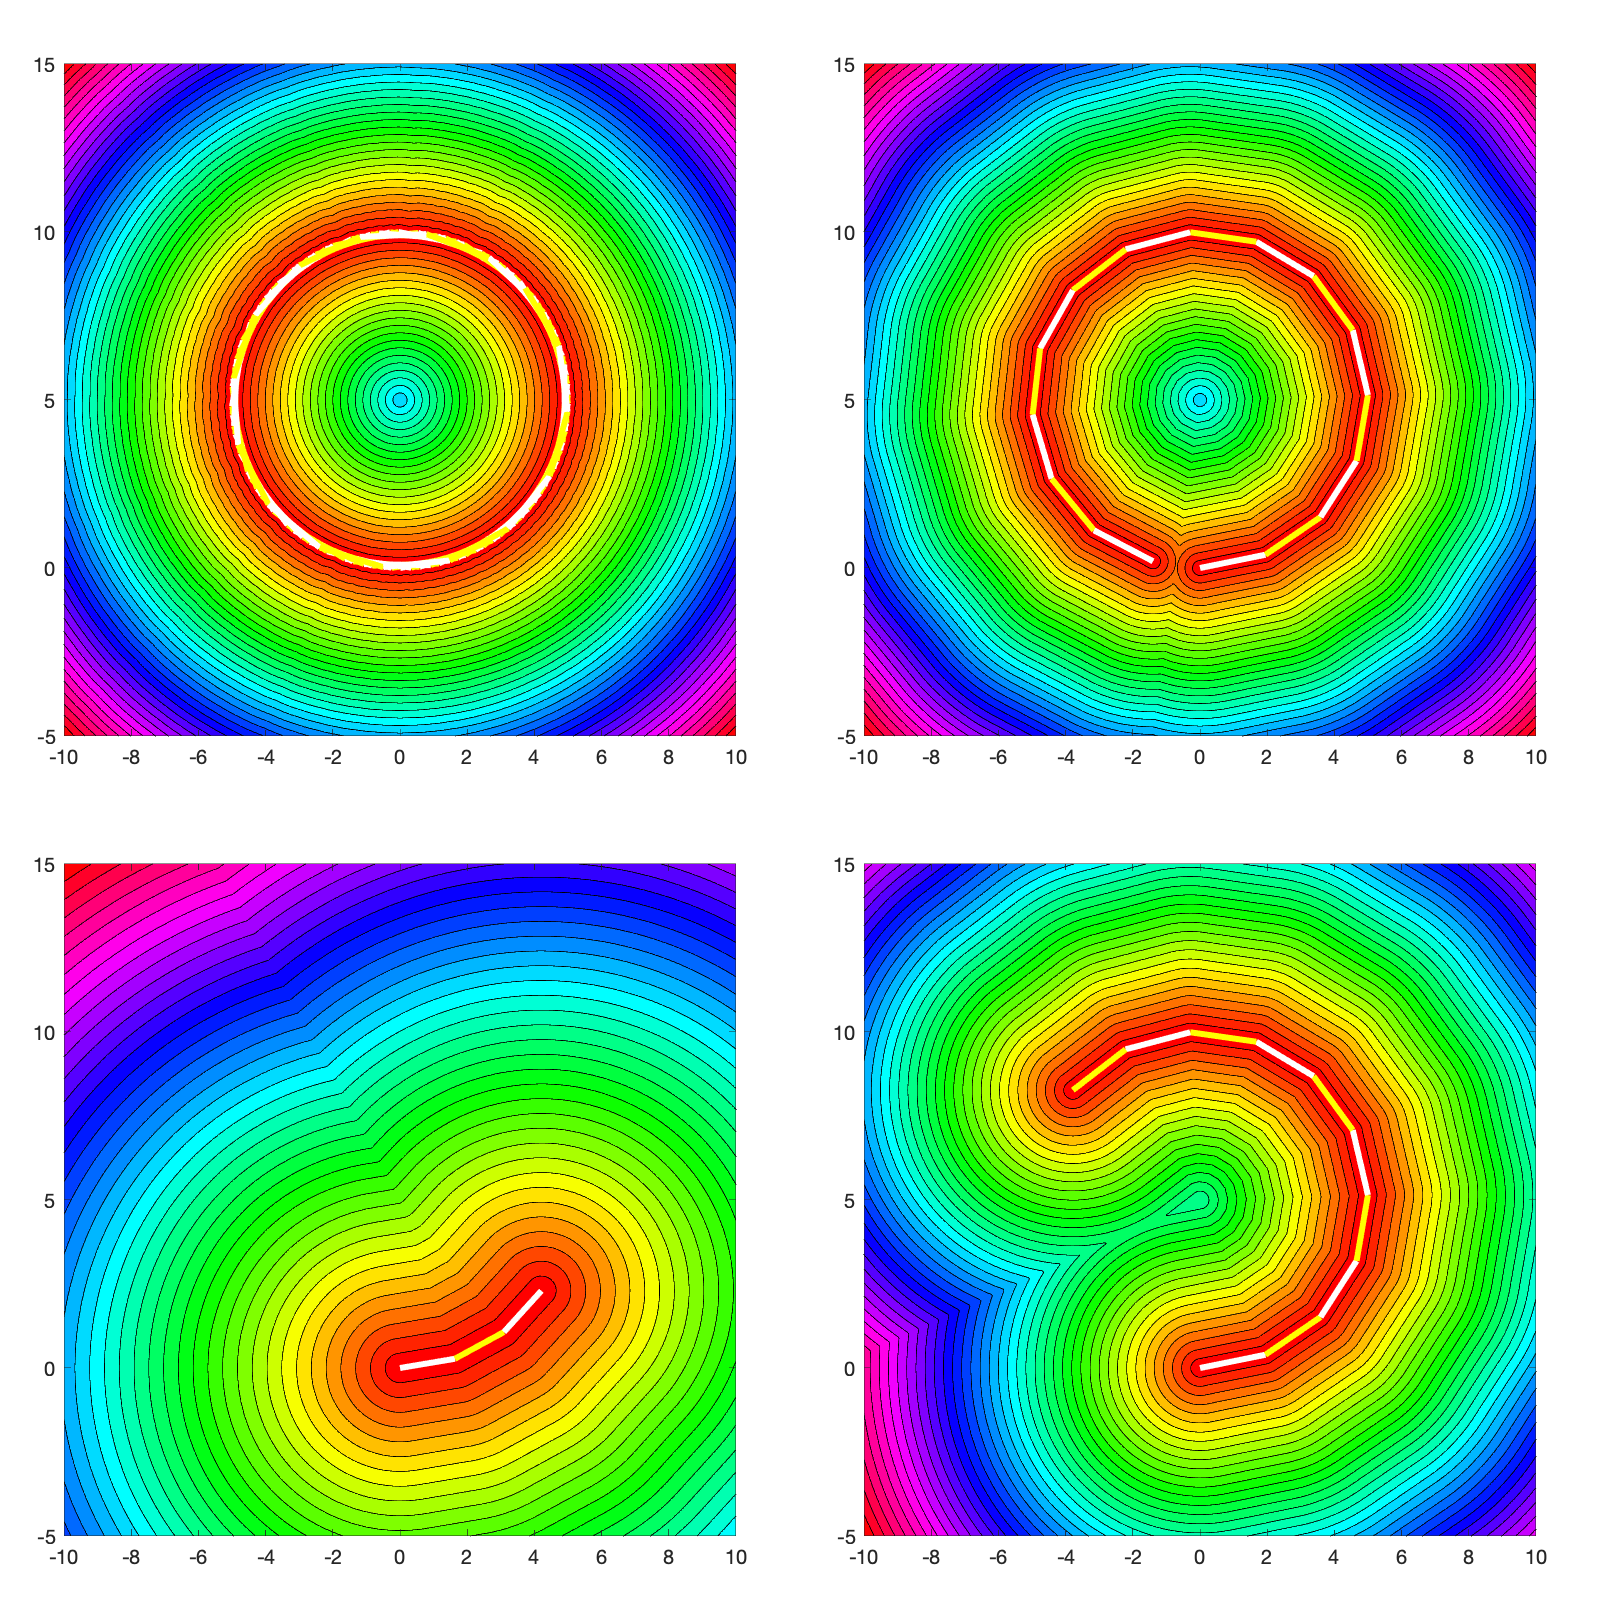

Elapsed time is 0.019338 seconds.


Elapsed time is 0.046465 seconds.


Elapsed time is 0.071512 seconds.


Elapsed time is 0.347082 seconds.


close all;

% check constructors
x0     = [0,0,0,0];
y0     = [0,0,0,0];
theta0 = 0;
kappa0 = [0.2, 0.2, 0.2, 0.2];
L      = [5,20,30,200];

aa = 0.04;
bb = 0.5-2*aa;

figure('Position',[ 1 1 800 800]);

for kk=1:4

  switch(kk)
  case 1; subplot('Position',[aa aa bb bb]);
  case 2; subplot('Position',[aa+0.5 aa bb bb]);
  case 3; subplot('Position',[aa+0.5 aa+0.5 bb bb]);
  case 4; subplot('Position',[aa aa+0.5 bb bb]);
  end

  %subplot(2,2,kk);
  L1 = CircleArc( x0(kk), y0(kk), theta0, kappa0(kk), L(kk) );
  P1 = PolyLine();

  P1.approx( L1, 0.1 );

  %
  x     = -10:0.05:10;
  y     = -5:0.05:15;
  [X,Y] = meshgrid(x,y);

  tic
  Z = P1.distance(X,Y);
  toc
  %colormap(prism);
  colormap(hsv);
  contourf(X,Y,Z,40);
  %surf(X,Y,Z)
  axis equal;
  hold on;
  P1.plot({'Color','White','Linewidth',3},{'Color','Yellow','Linewidth',3});
  %
  P1.delete();
end